# KF

## generate data

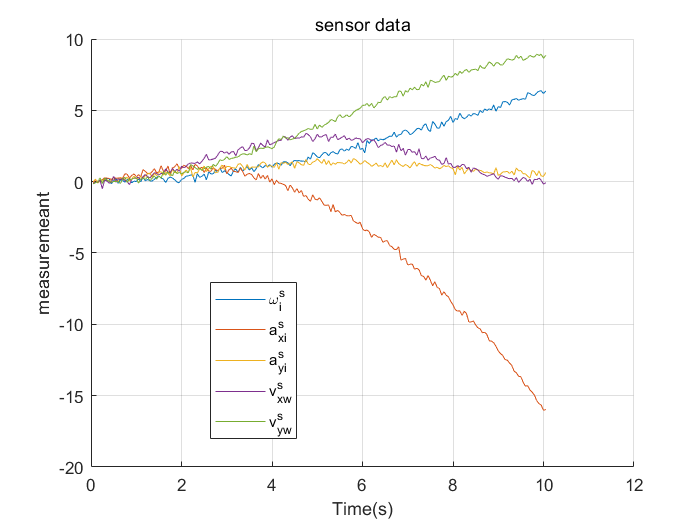

% mechanic model
beta = 0; %3.14/8;
phi = 0; %3.14/6;
d = 0.40;

% acc in sine wave
T = 0.05;
time_slice = T:T:T*length(ang);

ang_acc = sin((0:0.0025*pi:pi/2));
ang_vel = [0];
for i = 1:length(ang_acc)-1
    ang_vel(i+1) = ang_vel(i) + T*ang_acc(i);
end
ang = [0];
for i = 1:size(ang_vel, 2)-1
    ang(i+1) = ang(i) + T*ang_vel(i);
end

acc = [sin(0:0.01*pi:2*pi); sin((0:0.005*pi:pi))];
vel = [0; 0];
for i = 1:size(acc, 2)-1
    vel(:, i+1) = vel(:, i) + T*acc(:, i);
end
pst = [0; 0];
for i = 1:size(vel, 2)-1
    pst(:, i+1) = pst(:, i) + T*[cos(ang(i)), -sin(ang(i)); sin(ang(i)), cos(ang(i))]*vel(:, i);
end


real_state_vector = [pst; ang; vel; ang_vel; acc; ang_acc];

H_mat = [0, 0, 1, 0, 0, 0;
        0, 0, 0, cos(beta), sin(beta), -d*sin(phi-beta); ...
        0, 0, 0, -sin(beta), cos(beta), d*cos(phi-beta); ...
        cos(beta), sin(beta), -d*sin(phi-beta), 0, 0, 0; ...
        -sin(beta), cos(beta), d*cos(phi-beta), 0, 0, 0];
H_mat = [zeros([5, 3]), H_mat];
sensor_data = H_mat * real_state_vector;
sensor_data(2:3, :) = sensor_data(2:3, :) + ...
    [-ang_vel.^2 * d * cos(phi-beta); -ang_vel.^2 * d * sin(phi-beta)];
sensor_data = sensor_data + randn(size(sensor_data))*0.15;
figure; hold on;
for i = 1:5
    plot(time_slice, sensor_data(i, :))
end
hold off; xlabel("Time(s)"); ylabel("measuremeant"); title("sensor data"); grid on
legend(["\omega^s_i", "a_x_i^s", "a_y_i^s", "v_x_w^s", "v_y_w^s"], "Location", "best");

## KF

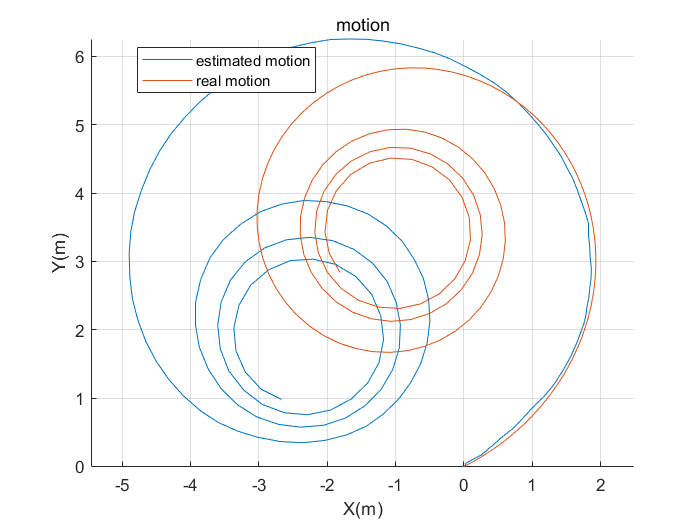

state_vector = zeros([9, 1]);
P = 0.01*diag(ones([1, 9]));
Q = 0.008*diag(ones([1, 9])); % tunable
R = 0.0225 * diag(ones([1, 5])); % tunable(0.15^2)
for i = 1:size(sensor_data, 2)-1
    % time update
    F = zeros([9, 9]) + diag(ones([1, 9]));
    F(3:6, 6:9) = T.*diag(ones([1, 4]));
    F(3, 9) = (T^2)/2;
    F(1:2, 4:9) = [T*cos(state_vector(3, end)), -T*sin(state_vector(3, end)), 0, ...
                    (T^2)/2*cos(state_vector(3, end)), -(T^2)/2*sin(state_vector(3, end)), 0; ...
                    T*sin(state_vector(3, end)), T*cos(state_vector(3, end)), 0, ...
                    (T^2)/2*sin(state_vector(3, end)), (T^2)/2*cos(state_vector(3, end)), 0];
    state_vector = [state_vector, F*state_vector(:, end)];
    F(1:2, 3) = [-T * sin(state_vector(3, end)) * state_vector(4, end) - ...
                T * cos(state_vector(3, end)) * state_vector(5, end) - ...
                (T^2/2) * sin(state_vector(3, end)) * state_vector(7, end) - ...
                (T^2/2) * cos(state_vector(3, end)) * state_vector(8, end); ...
                T * cos(state_vector(3, end)) * state_vector(4, end) - ...
                T * sin(state_vector(3, end)) * state_vector(5, end) + ...
                (T^2/2) * cos(state_vector(3, end)) * state_vector(7, end) - ...
                (T^2/2) * sin(state_vector(3, end)) * state_vector(8, end)];
    P = F * P * F' + Q;
    % measurement update
    H = [0, 0, 1, 0, 0, 0;
            0, 0, -2*state_vector(6, end)*d*cos(phi-beta), cos(beta), sin(beta), -d*sin(phi-beta); ...
            0, 0, -2*state_vector(6, end)*d*sin(phi-beta), -sin(beta), cos(beta), d*cos(phi-beta); ...
            cos(beta), sin(beta), -d*sin(phi-beta), 0, 0, 0; ...
            -sin(beta), cos(beta), d*cos(phi-beta), 0, 0, 0];
    H = [zeros([5, 3]), H];
    S = H * P * H' + R;
    K = P * H' * S^(-1);
    y = [state_vector(6, end); ...
        state_vector(7, end)*cos(beta) + state_vector(8, end)*sin(beta) - state_vector(6, end)^2*d*cos(phi-beta) - state_vector(9, end)*d*sin(phi-beta); ...
        -state_vector(7, end)*sin(beta) + state_vector(8, end)*cos(beta) - state_vector(6, end)^2*d*sin(phi-beta) + state_vector(9, end)*d*cos(phi-beta); ...
        state_vector(4, end)*cos(beta) + state_vector(5, end)*sin(beta) - state_vector(6, end)*d*sin(phi-beta); ...
        -state_vector(4, end)*sin(beta) + state_vector(5, end)*cos(beta) + state_vector(6, end)*d*cos(phi-beta)];
    epsilon = sensor_data(:, i) - y;
    state_vector(:, end) = state_vector(:, end) + K * epsilon;
    P = P - K * S * K';
end

figure; hold on;
plot(state_vector(1, :), state_vector(2, :));
plot(pst(1, :), pst(2, :));
legend(["estimated motion", "real motion"], "Location", "best");
xlabel("X(m)"); ylabel("Y(m)"); grid on; axis equal;
title("motion"); hold off

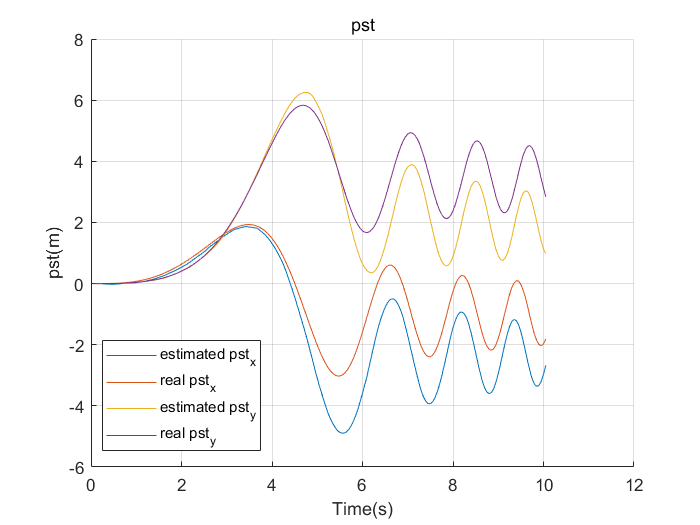


figure; hold on
plot(time_slice, state_vector(1, :));
plot(time_slice, pst(1, :));
plot(time_slice, state_vector(2, :));
plot(time_slice, pst(2, :));
legend(["estimated pst_x", "real pst_x", "estimated pst_y", "real pst_y"], "Location", "best");
xlabel("Time(s)"); ylabel("pst(m)"); grid on; 
title("pst"); hold off

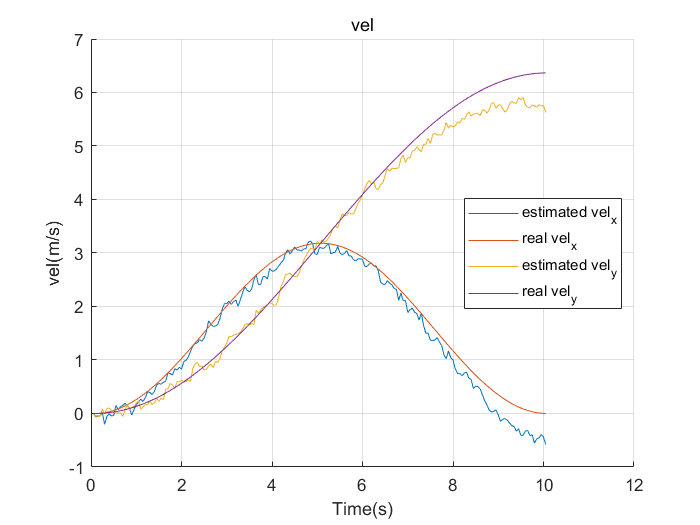


figure; hold on
plot(time_slice, state_vector(4, :));
plot(time_slice, vel(1, :));
plot(time_slice, state_vector(5, :));
plot(time_slice, vel(2, :));
legend(["estimated vel_x", "real vel_x", "estimated vel_y", "real vel_y"], "Location", "best");
xlabel("Time(s)"); ylabel("vel(m/s)"); grid on; 
title("vel"); hold off

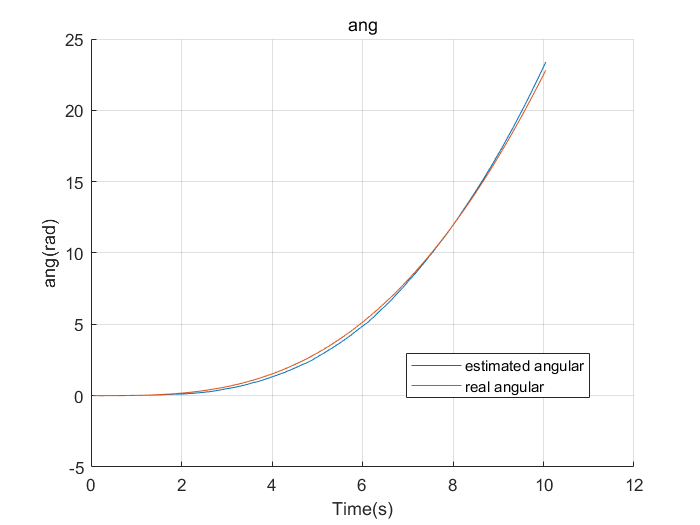


figure; hold on
plot(time_slice, state_vector(3, :));
plot(time_slice, ang);
legend(["estimated angular", "real angular"], "Location", "best");
xlabel("Time(s)"); ylabel("ang(rad)"); grid on; 
title("ang"); hold off

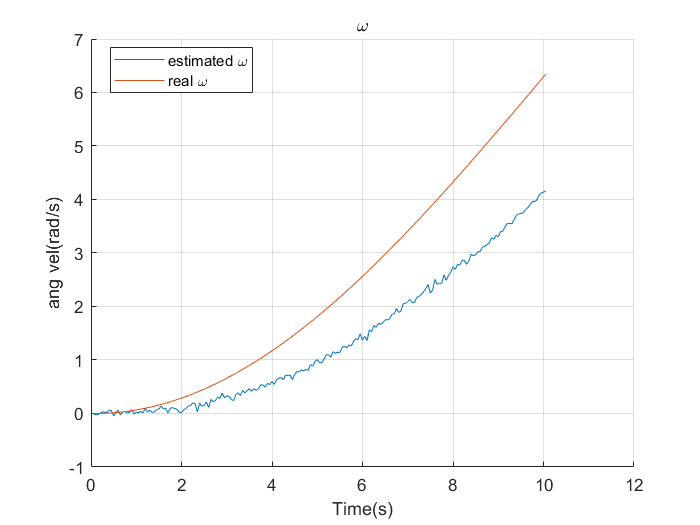


figure; hold on
plot(time_slice, state_vector(6, :));
plot(time_slice, ang_vel);
legend(["estimated \omega", "real \omega"], "Location", "best");
xlabel("Time(s)"); ylabel("ang vel(rad/s)"); grid on; 
title("\omega"); hold off